# Timeseries regression with LSTM.

Using an LSTM based Deep Neural Network, it is possible to forecast values in a dataset that has a direct correlation to time and the previous time steps. [Dataset can be acquired from this link.](https://archive.ics.uci.edu/ml/datasets/Power+consumption+of+Tetouan+city)

## Data preparation

Load, clean and split the data set. Chosen method of training the model is Hold Out Cross Validation with three datasets. Then change the data to have a 0 mean value and unit standard deviation, by subtracting the mean value and dividing with the standard deviation of the training dataset, from all three datasets.

close all
clear
clc

tbl = readtable("Tetuan City power consumption.csv");


tbl = rmmissing(tbl);
head(tbl)

        DateTime        Temperature    Humidity    WindSpeed    generalDiffuseFlows    diffuseFlows    Zone1PowerConsumption    Zone2PowerConsumption    Zone3PowerConsumption
    ________________    ___________    ________    _________    ___________________    ____________    _____________________    _____________________    _____________________

    01/01/2017 00:00       6.559         73.8        0.083             0.051              0.119                34056                    16129                    20241        
    01/01/2017 00:10       6.414         74.5        0.083              0.07              0.085                29815                    19375                    20131  


tbl = tbl(:, [1 end-2:end]);
head(tbl)

        DateTime        Zone1PowerConsumption    Zone2PowerConsumption    Zone3PowerConsumption
    ________________    _____________________    _____________________    _____________________

    01/01/2017 00:00            34056                    16129                    20241        
    01/01/2017 00:10            29815                    19375                    20131        
    01/01/2017 00:20            29128                    19007                    19668        
    01/01/2017 00:30            28229                    18361                    18899        
    01/01/2017 00:40            27336                    17872                    18442        
    01/01/2017 00:50            26625                    17416                    18130        
    01/01/2017 01:00            25999                    16993                    17945        

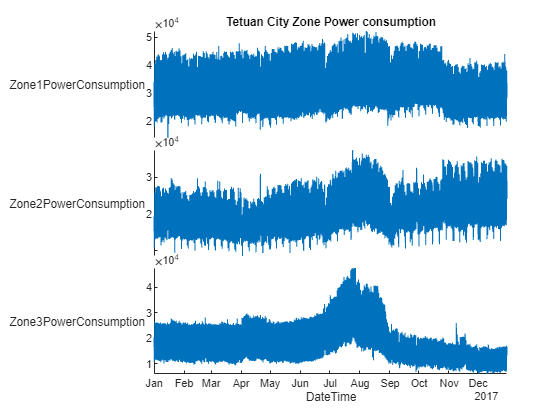


figure
stackedplot(tbl, "XVariable", "DateTime")
title("Tetuan City Zone Power consumption")


data = groupSequences(tbl, "DateTime");
[train_data, val_data, test_data] = splitSequence(data);
clear tbl data


muPredictors = mean(cat(2, train_data{:, 1}), 2);
sigmaPredictors = std(cat(2,train_data{:, 1}), 0, 2);

muResponses = mean(cat(2, train_data{:, 2}), 2);
sigmaResponses = std(cat(2, train_data{:, 2}), 0, 2);

for i = 1:size(train_data, 1)
    train_data{i, 1} = (train_data{i, 1} - muPredictors) ./ sigmaPredictors;
    train_data{i, 2} = (train_data{i, 1} - muResponses) ./ sigmaResponses;

    val_data{i, 1} = (val_data{i, 1} - muPredictors) ./ sigmaPredictors;
    val_data{i, 2} = (val_data{i, 1} - muResponses) ./ sigmaResponses;

    test_data{i, 1} = (test_data{i, 1} - muPredictors) ./ sigmaPredictors;
    test_data{i, 2} = (test_data{i, 1} - muResponses) ./ sigmaResponses;
end

## Network architecture, training options and network training.

The dataset contains 3 time series based features. Hyperparameters were chosen manually by examining the model's training graph. Architecture was also manually tweaked based on the same criterion.

features = 3;

% Hyperparameters
hidden_units = 256;
max_epochs = 100;
epoch_drop_period = 30;
batch_size = 32;
grad_thresh = 1;
ilr = 1e-1;


layers = [
    sequenceInputLayer(features)
    fullyConnectedLayer(hidden_units)
    lstmLayer(hidden_units, "OutputMode", "sequence")
    dropoutLayer(0.5)
    fullyConnectedLayer(features)
    regressionLayer
    ]

layers =   6×1 Layer array with layers:

     1   ''   Sequence Input      Sequence input with 3 dimensions
     2   ''   Fully Connected     256 fully connected layer
     3   ''   LSTM                LSTM with 256 hidden units
     4   ''   Dropout             50% dropout
     5   ''   Fully Connected     3 fully connected layer
     6   ''   Regression Output   mean-squared-error


opts = trainingOptions( ...
    "adam", ...
    "MaxEpochs", max_epochs, ...
    "MiniBatchSize", batch_size, ...
    "ValidationData", {val_data(:, 1), val_data(:, 2)}, ...
    "GradientThreshold", grad_thresh, ...
    "InitialLearnRate", ilr, ...
    "LearnRateSchedule", "piecewise", ...
    "LearnRateDropPeriod", epoch_drop_period, ...
    "Shuffle", "every-epoch", ...
    "Plots", "training-progress", ...
    "Verbose", true, ...
    "OutputNetwork", "best-validation-loss" ...
    )

opts =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.1000
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 30
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: 1
                       MaxEpochs: 100
                   MiniBatchSize: 32
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: {{364×1 cell}  {364×1 cell}}
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
   

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |         7.27 |         4.52 |      26.4427 |      10.2438 |          0.1000 |
|       5 |          50 |       00:00:13 |         1.09 |         0.63 |       0.5911 |       0.1999 |          0.1000 |
|      10 |         100 |       00:00:15 |         0.76 |         0.64 |       0.2895 |       0.2033 |          0.1000 |
|      14 |         150 |       00:00:17 |         0.59 |         0.61 |       0.1745 |       0.1854 |          0.1000 |
|      1

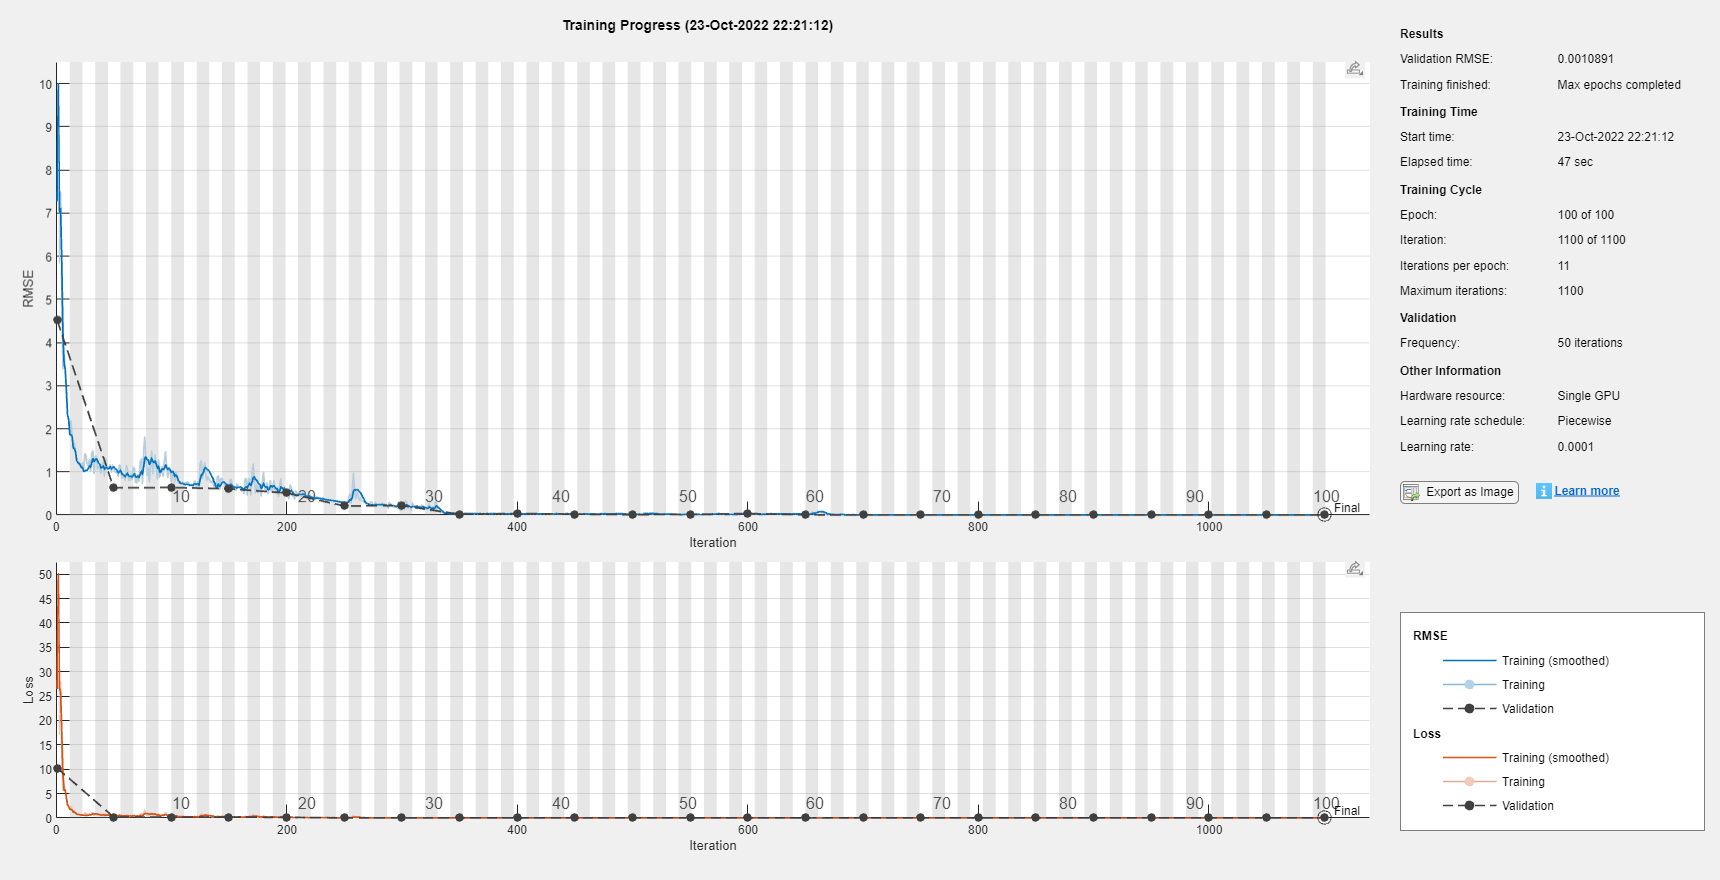


net = trainNetwork(train_data(:, 1), train_data(:, 2), layers, opts);

clear train_data val_data features hidden_units max_epochs epoch_drop_period batch_size grad_thresh ilr

## Testing the network.

Using the test dataset, predictions are made and a Root Mean Square Error (RMSE) is calculated. Moreover, a histogram from the RMSE of the sequences is drawn, that shows the amount of errors corresponding to a specific value of the RMSE matrix. Lastly, the ground truth and the predictions for the first sequence in the testing dataset are plotted in order to see the difference between the two.

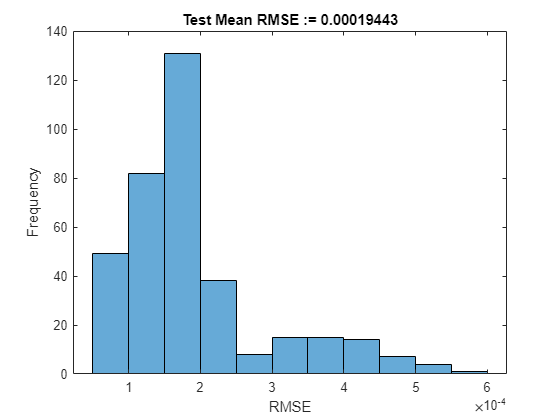

test_preds = predict(net, test_data(:, 1));

rmse = zeros(size(test_preds, 1), 1);
for i = 1:size(test_preds,1)
    rmse(i) = sqrt(mean((test_preds{i} - test_data{i, 2}).^2,"all"));
end
mrmse = mean(rmse);
clear i

figure
histogram(rmse)
xlabel("RMSE")
ylabel("Frequency")
title("Test Mean RMSE := " + num2str(mrmse))

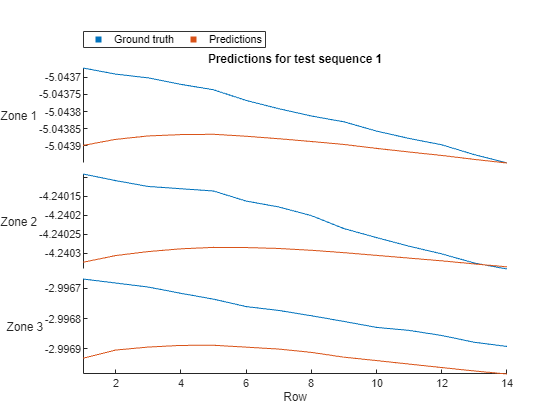


tbl1 = table(test_data{1, 2}(1, :)', test_data{1, 2}(2, :)', test_data{1, 2}(3, :)', 'VariableNames', ["Zone 1", "Zone 2", "Zone 3"]);
tbl2 = table(test_preds{1}(1, :)', test_preds{1}(2, :)', test_preds{1}(3, :)', 'VariableNames', ["Zone 1", "Zone 2", "Zone 3"]);

stackedplot(tbl1, tbl2, "LegendLabels", ["Ground truth", "Predictions"], "Title", "Predictions for test sequence 1")

clear t tbl1 tbl2 test_data test_preds rmse mrmse
save powerConsumptionNet.mat